clc;clear;
% % % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% % data = fread(fid,'short');
% data = read_complex_binary('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf80_total.dat');
% load("/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/heltf80_total.mat")
% % load('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/HELTF80_tx_bb.mat');

% i = 3;
% symbollen_table = [288, 576, 1152];
% gilen_table = [32, 64, 128];

% symbollen = symbollen_table(i);
% gilen = gilen_table(i);
% 

% % time domain
% N0 = 2514;
% figure
% plot(real(data))
% hold on
% plot(imag(data))
% hold on
% % plot(imag(data(N0+1:N0+288)))
% % hold on 
% % plot(real(bb(1,:))./ 1.5)
% % hold on 
% 
% 
% figure
% corr_result = conv(data, bb(1,:));
% plot(abs(corr_result))
% hold on
% 
% figure()
% Fs = 200e6;
% t = 0:1/Fs:0.000001-1/Fs % 1000 points
% N = length(t);
% y0 = abs(fft(data(N0+1:N0+N)));
% f = (0:N-1)*Fs/N;
% plot(f,y0);
% % plot(abs(fftshift((fft(data(1:10000))))))
% hold on 
% 
% figure()
% f1 = (0:N-1)*Fs/N-Fs/2;
% y1 = abs(fftshift(fft(data(N0+1:N0+N))));
% plot(f1,y1);
% hold on
% 
% figure
% cfr_bb = fftshift(fft(transmit_bb(cfg.gilen+1:end)));
% plot(abs(cfr_bb))
% hold on
% 
% % decode part 
% % freq shift
% % fc = 5825e6;
% % baseband_data = data.* exp(2*pi*1i*f_center*t);
% % loc_carr = exp(-1i*2*pi*(0:length(data)-1)*fc/Fs)';
% % data = data.*loc_carr;
% 
% pos = N0;
% cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';
% plot(abs(cfr_recv))
% hold on
% % plot(real(cfr_recv))
% % hold on
% -
% cir1 = zeros(cfg.users, cfg.fftlen);
% 
% figure
% for u=1:cfg.users
% cir1(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% plot(abs(cir1(1,:)))
% hold on
% end



% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% data = fread(fid,'short');
% data = read_complex_binary('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf80_rx2.dat');
data = read_complex_binary('/mnt/tmp/usrp_160_SFO_fs_1k_breathe.dat');
load("/home/dellx/文档/uhd/host/Simulation_RU/Simulation_RU/heltf160.mat")
% load('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/HELTF80_tx_bb.mat');

i = 4;
symbollen_table = [288, 576, 1152, 2304];
gilen_table = [32, 64, 128, 256];
symbollen = symbollen_table(i);
gilen = gilen_table(i);


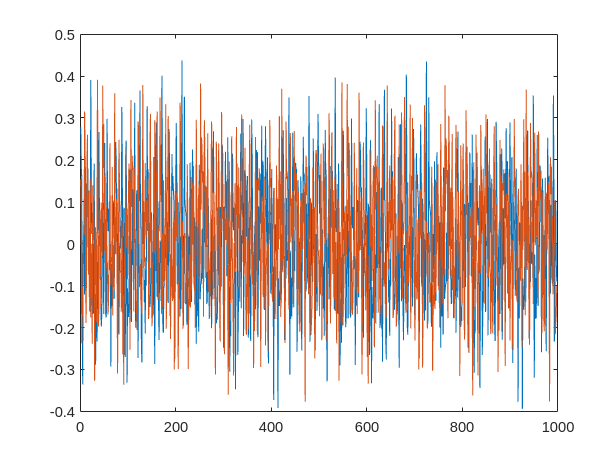

% time domain
N0 = 3194; % 3194
figure
plot(real(data(1:998)))
hold on
plot(imag(data(1:998)))

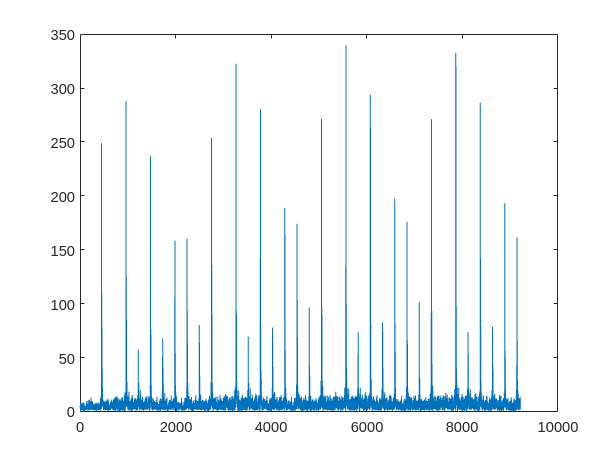

% plot(imag(data(N0+1:N0+288)))1913
% hold on 
% plot(real(bb(1,:))./ 1.5)
% hold on 
% 
% tic

% figure
% plot(abs(corr_result(1:2304*10)))
% hold on
% toc



N_cir = 50;

% corr_result = zeros(2304*N_cir,1);
% 
% for i = 1:N_cir
%     corr_result(2304*(i-1)+1 : 2304*(i-1) + 2304) =  conv(data(1:1*symbollen), bb(1,1:end), 'same');theta = angle(cfo_2);
% end

tic
figure
corr_result = conv(data(1:2304*N_cir), bb(1,1:end), 'same');
% plot(abs(corr_result(1:200000)))
plot(abs(corr_result(1:2304*4)))
hold on

toc

历时 0.036878 秒。



corr_result = [corr_result; zeros(symbollen - mod(length(corr_result), symbollen), 1)]; 
corr_result2 = reshape(corr_result, [symbollen, length(corr_result) / symbollen]);

cfo_2 = corr_result2(1152,:) + corr_result2(1153,:);

t = 1:N_cir+1;
theta = angle(cfo_2);
Q = unwrap(theta)

Q =    -1.0306    1.6920    4.1864    6.5945    8.7168    9.5740   10.7114   12.1897   13.3285   14.6778   16.3251   18.0733   19.1850   20.4266   21.9845   23.8875   23.2585   25.8974   25.8889   23.0041   21.1406   18.3583   15.8967   13.5179   15.0025   17.6781   18.9311   21.4245   24.0868   25.3350   22.8313   21.7667   21.2924   19.7642   16.9578   14.0065   11.5820    9.9665    7.7739   10.4916    7.4569    4.8043    2.1493    3.7219    6.2980    6.7441    9.8824    7.0790    7.7269    5.2045


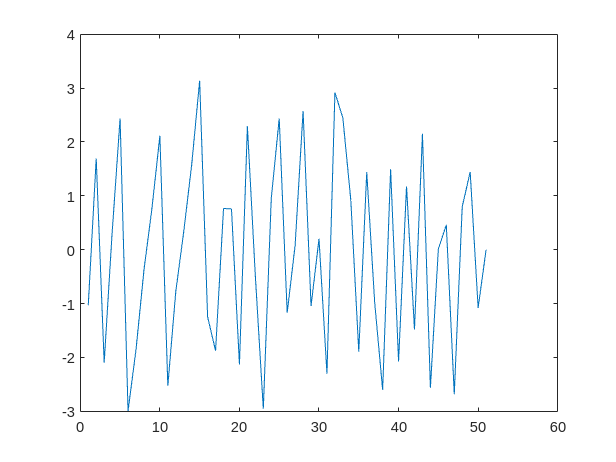

figure
plot(t, theta)
hold on

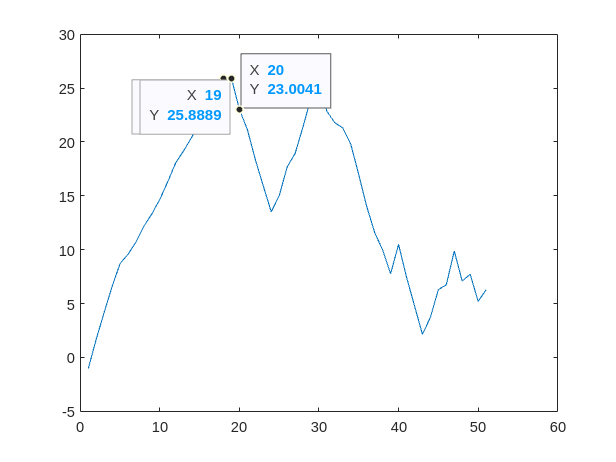


figure 
plot(Q)
hold on

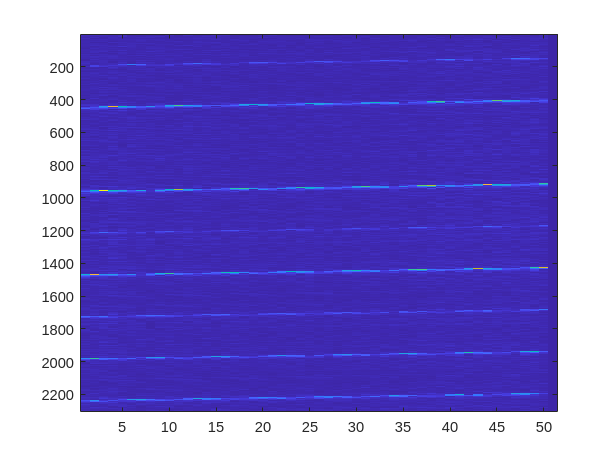


% for i = 1:N_cir
%     corr_result2(:, i) = circshift(corr_result2(:, i),1,1);
% end

figure
imagesc(abs(corr_result2))
% ylim([1100, 1150])
% xlim([1 1500])data
hold on

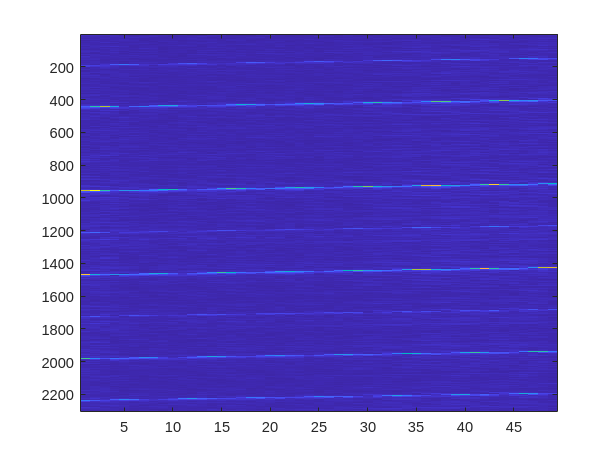


corr_dif = diff(corr_result2, 2, 2);
figure
imagesc(abs(corr_dif))
% ylim([850, 950])
hold on

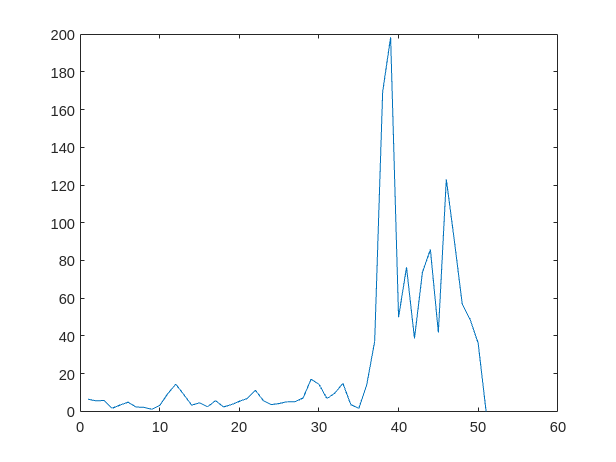


% tic
% % rewrite corr_
% n = length(data) + length(bb(1,:)) -1;1
% fft_bb = fft(bb(1,:), n);
% fft_data = fft(data, n)';t % wave_table_len
% corr_result = ifft(fft_data .* fft_bb);
% figure
% plot(abs(corr_result(1:20000)))
% hold on1
% toc 100

N1 = 411;
figure
plot(abs(corr_result2(N1+1,:)))
hold on

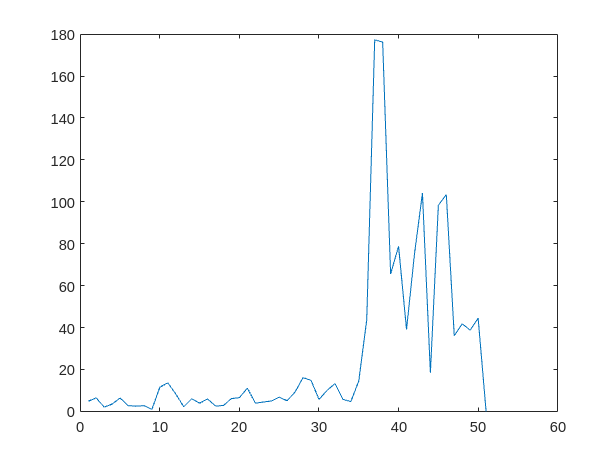


figure
plot(abs(corr_result2(N1+2,:)))
hold on

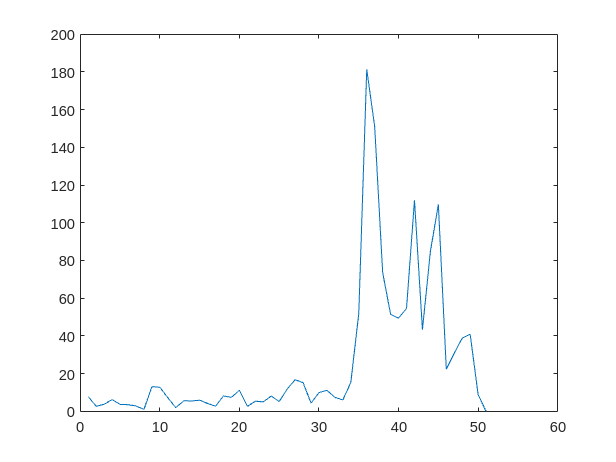


figure
plot(abs(corr_result2(N1+3,:)))
hold on

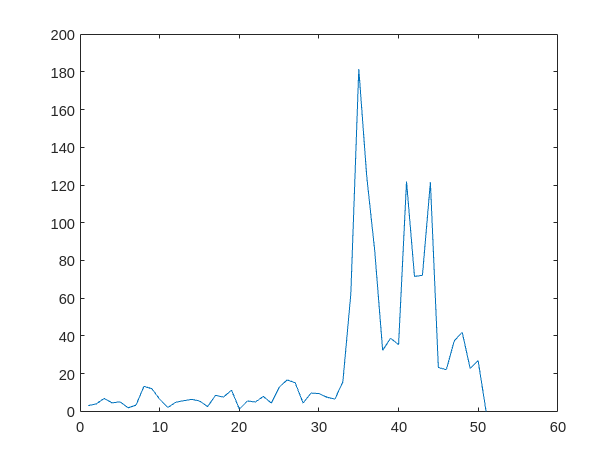


figure
plot(abs(corr_result2(N1+4,:)))
hold on

% decode part 

row = 0;
num = 4209

num = 4209

cir2 = zeros(num+1, cfg.fftlen);

for N = N0:symbollen:N0+num*symbollen
pos = N;
row = row+1;
cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';

% plot(abs(cfr_recv))
% hold on
% plot(real(cfr_recv))
% hold on

t3 = 1:12.5:12.5*1024;
cir2(row,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));

end

索引超过数组元素的数量。索引不能超过 214528。


% % % rewrite cir2
% data_length = num;
% despread_data = [];
% shaped_corr = reshape(corr_result(1:symbollen*num),symbollen,num);
% % find the index of the max values (relative position)
% [~,max_index] = max(abs(shaped_corr),[],1)
% %
% col_index = 0:symbollen:(num-1)*symbollen
% really_index = max_index+col_index;
% despread_data = corr_result(max_index+col_index);
% % for loop
% % cfr_recv = zeros(num,1024);% % rewrite cir2
% data_length = num;
% despread_data = [];
% shaped_corr = reshape(corr_result(1:symbollen*num),symbollen,num);
% % find the index of the max values (relative position)
% [~,max_index] = max(abs(shaped_corr),[],1)
% %
% col_index = 0:symbollen:(num-1)*symbollen
% really_index = max_index+col_index;
% despread_data = corr_result(max_index+col_index);
% % for loop
% % cfr_recv = zeros(num,1024);
% start_index = really_index + ones(1,num) *(gilen+1);
% end_index = really_index + ones(1,num) * symbollen;
% for i = 1 : num
%     cfr_recv = fftshift(fft(data(start_index(i):end_index(i))))';
%     cir2(i,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% end
% start_index = really_index + ones(1,num) *(gilen+1);
% end_index = really_index + ones(1,num) * symbollen;
% for i = 1 : num
%     cfr_recv = fftshift(fft(data(start_index(i):end_index(i))))';
%     cir2(i,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% end

figure
plot(abs(cir2(:,254)))
hold on

figure
plot(abs(cir2(:,255)))
hold on

figure
plot(abs(cir2(:,256)))
hold on

figure
plot(abs(cir2(:,257)))
hold on

figure
plot(abs(cir2(:,258)))
hold on
figure
plot(abs(cir2(:,259)))
hold on

figure
plot(abs(cir2(:,260)))
hold on


% figure-
% plot(abs(cir2(:,131)))% % rewrite cir2num
% data_length = num;
% despread_data = [];
% shaped_corr = reshape(corr_result(1:symbollen*num),symbollen,num);
% % find the index of the max values (relative position)
% [~,max_index] = max(abs(shaped_corr),[],1)
% %
% col_index = 0:symbollen:(num-1)*symbollen
% really_index = max_index+col_index;
% despread_data = corr_result(max_index+col_index);
% % for loop
% % cfr_recv = zeros(num,1024);
% start_index = really_index + ones(1,num) *(gilen+1);
% end_index = really_index + ones(1,num) * symbollen;
% for i = 1 : num1913
%     cfr_recv = fftshift(fft(data(start_index(i):end_index(i))))';
%     cir2(i,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% end
% hold on
% -
% figure
% plot(abs(cir2(:,132)))
% hold on

figure
for u=1:cfg.users
cir2(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
plot(1:25:25*2000,abs(cir2(1,1:2000)))
% plot(1:50:50*1024, abs(cir2(1,:)))
hold on

end
xlabel('Delay(ns)')
ylabel('amplitude')
title('CIR')

